# **CS/SE 4X03 Tutorial 3**

## Horner's Algorithm

Horner's algorithm is used to evaluate a polynomial of degree $n\;$with  $n\;$multiplications and $n\;$additions. 

Consider the polynomial 

$p(x) = a_0 + a_1x +a_2x^2+\cdots+a_nx^n$.

**Example. **$\;\;\textrm{Let}\;$$p(x) = 2x^3 - 7x^2 + 3x + 5$.

One way to evaluate it is e.g.

clear all;
a = [2, -7, 3, 5]; 
x=.5; 

p = a(1);
t = x;      
for i = 2:length(a)  
    p = p+a(i)*t;      % 1 addition, 1 multiplication
    t = t*x;           % 1 multiplication
end
p

p = -0.1250

Here we have $N-1$ additions and $2(N-1)$ multiplications. The degree of the polynomial is $n=N-1$. Therefore, for a degree $n$ polynomial, this approach has $n$ additions and  $2n\;\textrm{multiplications}\ldotp$

We can rewrite $p(x) = a_0 + a_1x +a_2x^2+\cdots+a_nx^n$ as 


$$h(x) = a_0 + x(a_1 + x(a_2 +\cdots+x(a_{n-1}+x(a_n))\cdots))$$


**Example. **We can rewrite 


$$\begin{array}{ll}
p(x) &= 2x^3 - 7x^2 + 3x + 5\\
& \text {as}\\
h(x) &= 5 + x(3 + x(-7 + x(2)))
\end{array}$$


% Horners method
h = a(end); 
for i = length(a) : -1 : 1
    h = a(i)+x*h;  % 1 addition, 1 multiplication
end
h

h = -0.1250

This has  $n$ additions and $n$multiplications, which is the lowest possible number of arithmetic operations. 

## Exercise 1 - 1.2.15

**Q: **Determine the** first four** nonzero terms in the series expansion about zero for:

**a) **$f = \sin(x) + \cos(x)$and find an approximate value for $f(0.001)$

**b) **$g = \sin(x)\cos(x)$ and find an approximate value for $g(0.0006)$

**Recall:**


$$\begin{array}{ll}
\sin(x) &= x - \frac{x^3}{3!} + \frac{x^5}{5!} - \frac{x^7}{7!} + \cdots\\
\cos(x) &= 1 - \frac{x^2}{2!} + \frac{x^4}{4!} - \frac{x^6}{6!} + \cdots
\end{array}$$


**a) **


$$\begin{array}{ll}
\sin(x) + \cos(x) &= 1 + x - \frac{x^2}{2} - \frac{x^3}{6} + O(x^4)\\
\sin(0.001) + \cos(0.001) &\approx 1 + 0.001 - \frac{0.001^2}{2} - \frac{0.001^3}{6} = 1.00099949983
\end{array}$$


**b)**


$$\begin{array}{ll}
\sin(x)\cos(x) &= x - \frac{x^3}{6} + \frac{x^5}{120} - \frac{x^7}{5040} - \frac{x^3}{2} + \frac{x^5}{12} - \frac{x^7}{240} + \frac{x^5}{24} - \frac{x^7}{720} + O(x^9)\\
\sin(x)\cos(x) &= x - \frac{2x^3}{3} + \frac{2x^5}{15} - \frac{4x^7}{315} + O(x^9)\\
\sin(0.0006)\cos(0.0006) &\approx 0.000599999857
\end{array}$$


## Exercise 2 - Cancellations in Floating-Point

### Question

In a floating-point system with precision $t = 6$ decimal digits, let $x = 1.23456$ and $y = 1.23579$

**a) **How many significant digits does the difference $y-x$ contain?

**b) **If the floating-point system is normalized, what is the minimum exponent range for which $x,y$ and $y-x$ are all exactly representable?

### Answer

**a)** We have


$$\begin{array}{ll}
y-x&=1.23579-1.23456 = 0.00123\\
 &= 1.23579\times10^{0} - 1.23456\times10^{0} = 0.00123\times 10^0\\
&= 1.23000\times10^{-3}
\end{array}$$


So we have three significant digits.

**b) **Using a normalized 6-digit decimal system we have:


$$\begin{array}{ll}
x &= 1.23456\times 10^0\\
y &= 1.23579\times10^0\\
y - x &= 1.23000\times10^{-3}
\end{array}$$


So to represent these values we need a range of exponents that is at least $[-3,0]$ since, in this system, this will allow us to represent $\text{fl}(x)\in[1.00000\times10^{-3},9.99999\times10^0]$

## **Exercise 3 - Another Look at Cancellation**

### **Question**

Consider


$$\begin{array}{ll}
f(x) &= \left(x-2\right)^9\\
&\text{and it's expansion}\\
g(x) &= x^9 - 18x^8 + 144x^7 - 672x^6 + 2016x^5 - 4032x^4 + 5376x^3 - 4608x^2 + 2304x - 512
\end{array}$$


Although these two functions are mathematically equivalent, when run in floating point, they can produce different results.

**a) **When do you expect the two functions to produce different results and why at this(these) value(s)? Similarly, which function do you expect to give you more precise results, and why?

**b) **Plot $f$ and $g$, centered around this(ese) problem point(s).

**c)** What would happen if you replaced `x` values in MATLAB with `single(x)`? Try it and reflect on how we might be able to reduce the error in the computation of $g(x\approx2)$.

### **Answer**

**a) **Since we are adding values of opposite signs, we should be concerned about the possibility of cancellation errors.  At $x=2$ we have $f(x)=0$ and these cancellations will be large relative to the answer. We can predict that the expanded version will provide less precise results.

**b)**

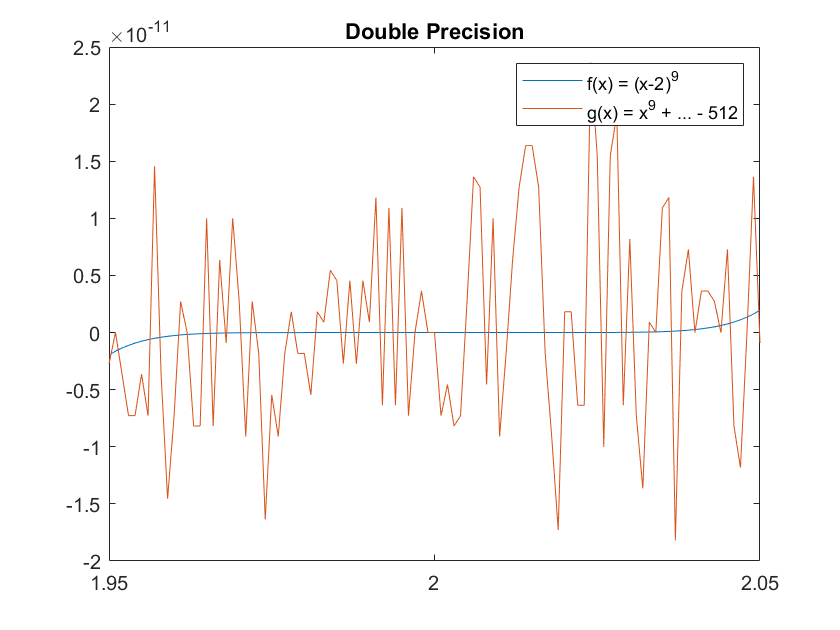

clear;
clf;
f = @(x)(x-2).^9;
g = @(x)x.^9 - 18*x.^8 + 144*x.^7 - 672*x.^6 + 2016*x.^5 - 4032*x.^4 + 5376*x.^3 - 4608*x.^2 + 2304*x - 512;

xmin = 1.95;
xmax = 2.05;
step= 0.001;

x = (xmin:step:xmax);
plot(x,[f(x); g(x)]);
title("Double Precision")
legend(["f(x) = (x-2)^9","g(x) = x^9 + ... - 512"])

Looking at the plot above, we can qualitatively see that $g(x)$ is much less accurate than $f(x)$ when $x\approx 2$.

Let's also consider what the error looks like, in both an absolute and relative sense. The relative error is going to be more insightful here, but it may help your intuition to see the two.

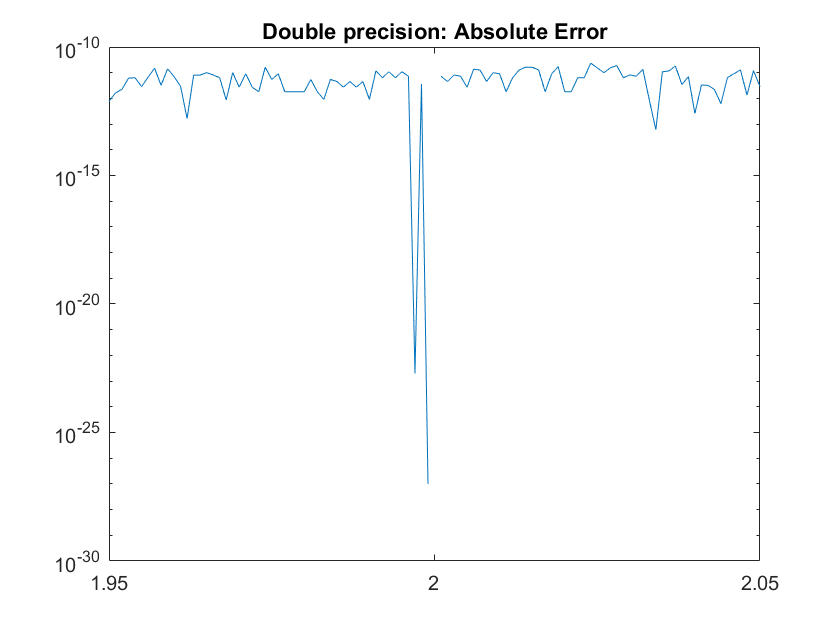

absErr = @(x) abs(f(x)-g(x));

semilogy(x,absErr(x));
title("Double precision: Absolute Error");

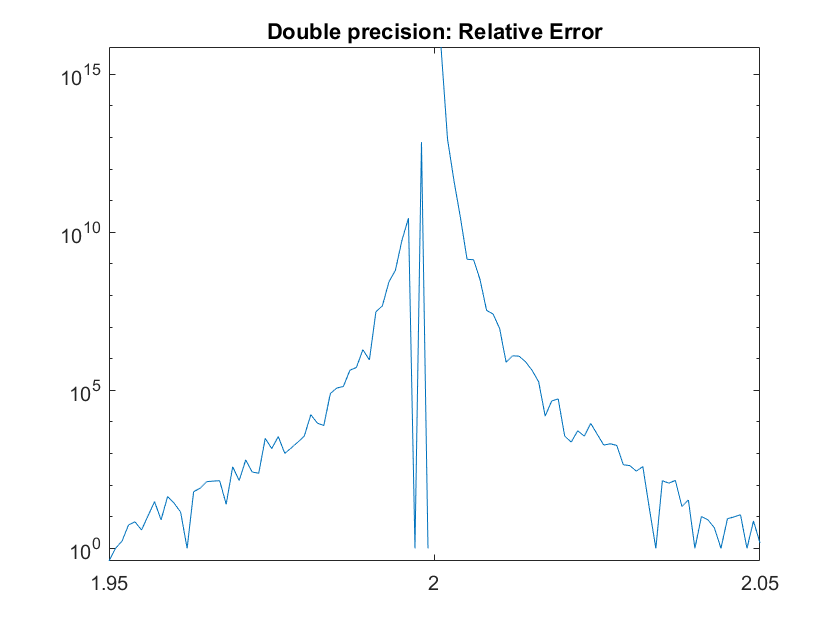

relError = @(x) absErr(x)./abs(f(x));
semilogy(x, relError(x));
title("Double precision: Relative Error");

The graph is disconnected at point for which the error evaluates to a NaN. This happens when $f(x) = g(x) = 0$, then the relative error evaluates to $0/0$, which results in a NaN. 

This confirms what we stated in part **a**, that we are going to have errors in $g(x)$ when $x\approx2$. 

**c)**

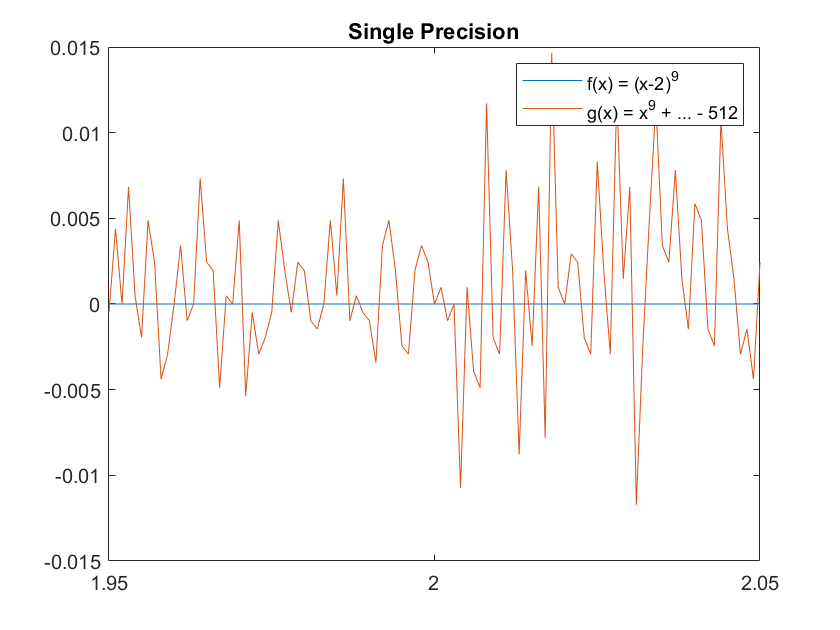

xs = single(x);
plot(xs,[f(xs); g(xs)])
title("Single Precision")
legend(["f(x) = (x-2)^9","g(x) = x^9 + ... - 512"])

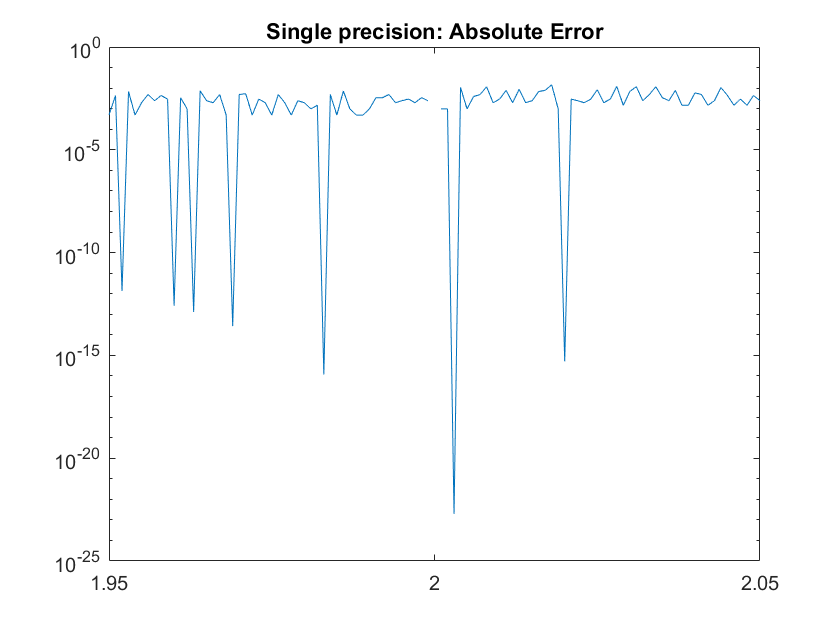

semilogy(xs,absErr(xs));
title("Single precision: Absolute Error");

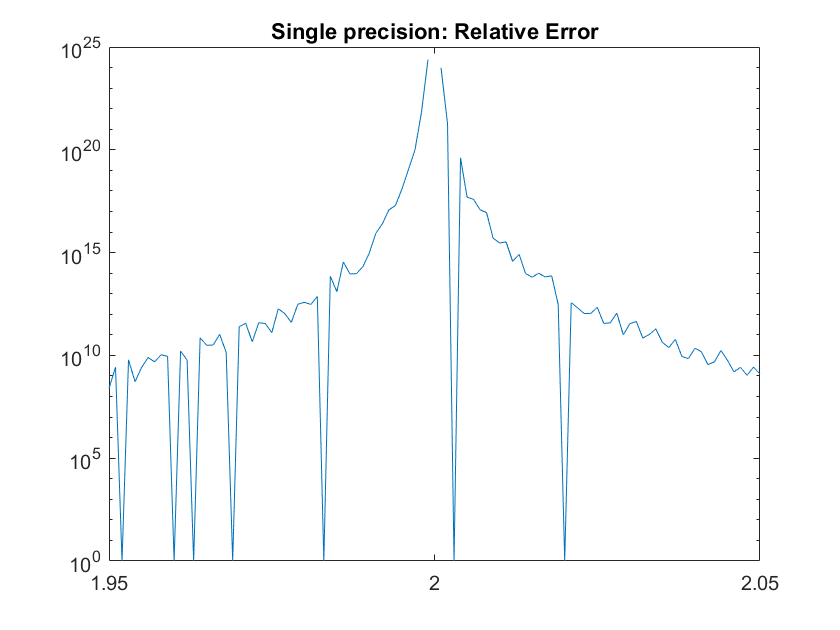

semilogy(xs, relError(xs));
title("Single precision: Relative Error");

By plotting using single precision, we can see that the error has increased *dramatically *(look at the axis scale!. Since the `single` command is calling our values with lower precision than default, we can infer that this is the result of a **cancellation error**. 

To deal with this, we can give ourselves more precision by using VPA

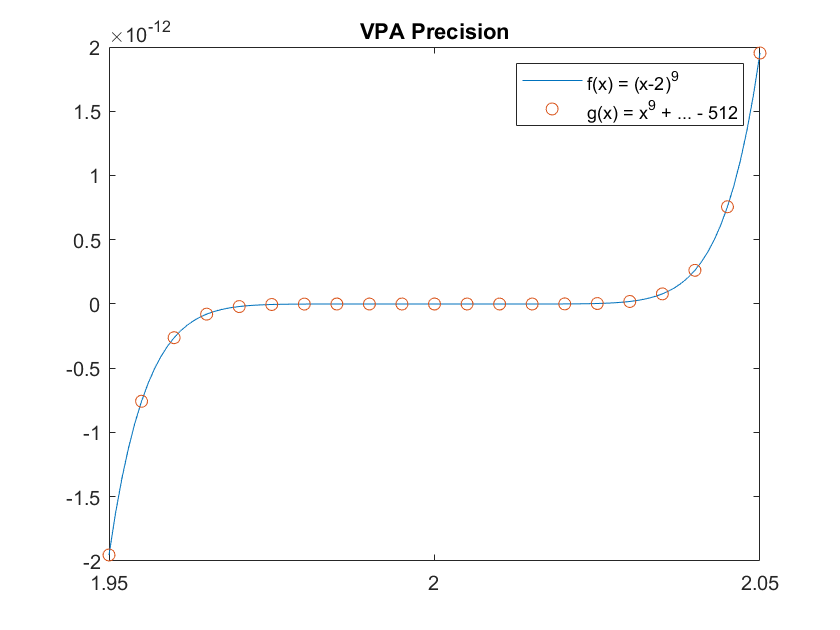

v = vpa(x);  % v contains at least 32 decimal digits by default
digits(32); % do the arithmetic in 32 digts
plot(x,f(v), v(1:5:end),g(v(1:5:end)),'o')
title("VPA Precision")
legend(["f(x) = (x-2)^9","g(x) = x^9 + ... - 512"])

This plot shows that our two functions have actually converged to each other. Tracking our calculation with more precision was all that we needed. If we added more precision, it would not decrease the error (from the scale we are viewing that is). 

As a final check, we can look at the relative error using vpa and we observe that now the relative error is much lower, even when $x\approx 2$.

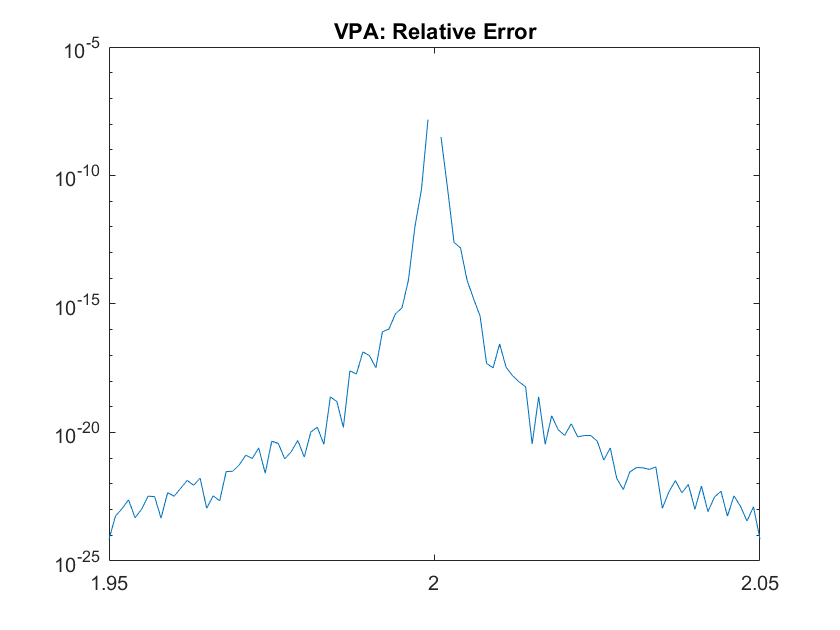

semilogy(v,relError(v));
title("VPA: Relative Error");

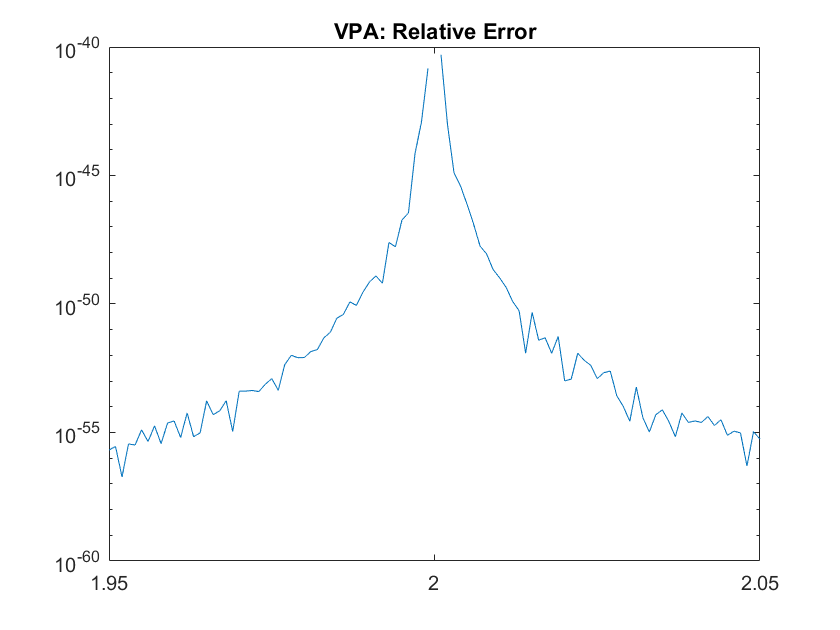

%evaluate in 64 digit arithmetic and plot the errors
v = vpa(x,64);
digits(64);
semilogy(v,relError(v));
title("VPA: Relative Error");